1,0,93

# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** : 이기준            **

**학번**** : 201710958**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

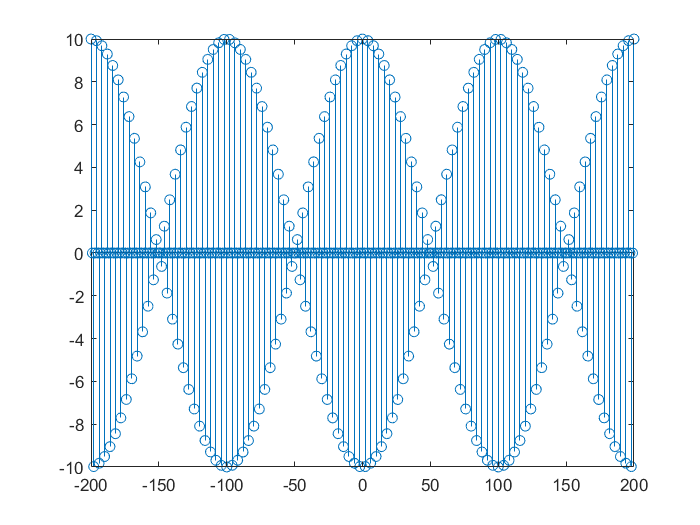

n = [-200:1:200];
xn = 5*cos(0.49*pi*n) + 5*cos(0.51*pi*n);
stem(n,xn);

2) 

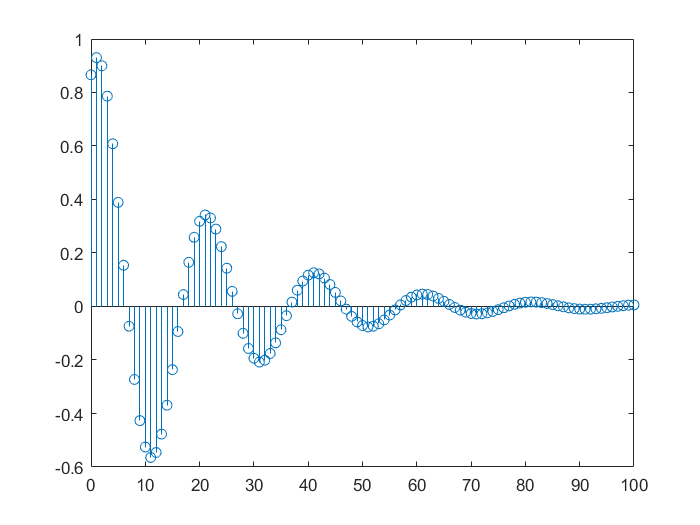

n = [0:1:100];
xn = exp(-0.05*n).*sin(0.1*pi*n+pi/3);
stem(n,xn);

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

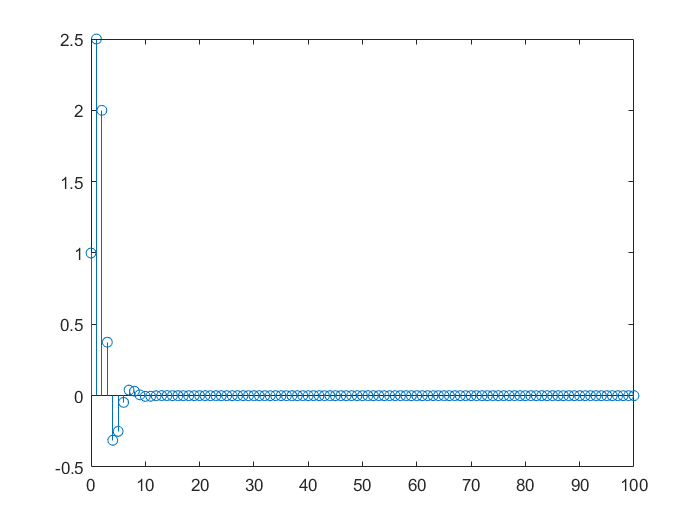

b = [1,2,1];
a = [1,-0.5,0.25];
n = [0:100];
h = impz(b,a,n);
stem(n,h);

2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

b = [1,2,1];
a = [1,-0.5,0.25];
n = [0:100];
h = impz(b,a,n);
sum(abs(h))

ans = 6.5714

%sum(abs(h)) = 6.5714 , 0<=n<=100인 구간에서 h의 모든 합이 6.5714이므로 안정함을 보여준다

3) 만약 이 시스템의 입력이  이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

% 입력신호 : x(n) = [5+3cos(0.2pin)+4sin(0.6pin)]u(n)
n = [0:200];
b = [1,2,1];
a = [1,-0.5,0.25];
xn = 5+3*cos(0.2*pi*n)+4*sin(0.6*pi*n)

xn =     8.0000   11.2313    3.5759    1.7218    6.3772    2.0000   -1.2313    6.4241    8.2782    3.6228    8.0000   11.2313    3.5759    1.7218    6.3772    2.0000   -1.2313    6.4241    8.2782    3.6228    8.0000   11.2313    3.5759    1.7218    6.3772    2.0000   -1.2313    6.4241    8.2782    3.6228    8.0000   11.2313    3.5759    1.7218    6.3772    2.0000   -1.2313    6.4241    8.2782    3.6228    8.0000   11.2313    3.5759    1.7218    6.3772    2.0000   -1.2313    6.4241    8.2782    3.6228


yn = filter(b,a,xn);
yn

yn =     8.0000   31.2313   47.6541   36.1241   19.5452   17.2177   12.8685    8.0913   20.7236   34.9423   35.8141   40.0256   45.0977   32.6474   18.4460   17.5373   13.3031    8.2287   20.6837   34.8880   35.7969   40.0306   45.1045   32.6495   18.4453   17.5364   13.3028    8.2288   20.6838   34.8880   35.7969   40.0305   45.1045   32.6495   18.4453   17.5364   13.3028    8.2288   20.6838   34.8880   35.7969   40.0305   45.1045   32.6495   18.4453   17.5364   13.3028    8.2288   20.6838   34.8880


3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

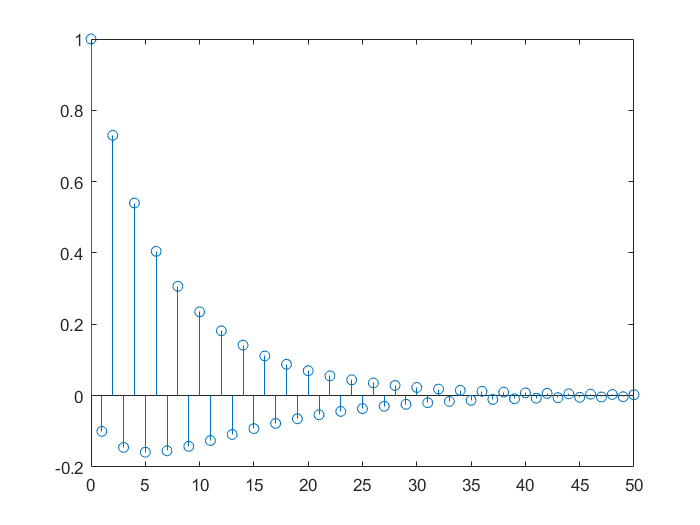

n = [0:50];
xn = 0.8.^n;
hn = (-0.9).^n;
yn = ((0.8).^(n+1) - (-0.9).^(n+1))/(0.8+0.9); %yn = convolution(xn,hn)
stem(n,yn);

2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

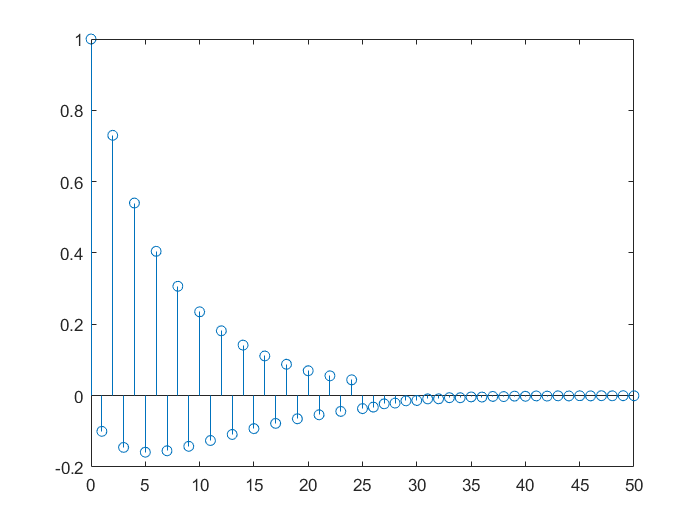

xn = 0.8.^n;
hn = (-0.9).^n;
x1 = xn(1:26);
h1 = hn(1:26);
y1 = conv(x1,h1);
stem(n,y1);

3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

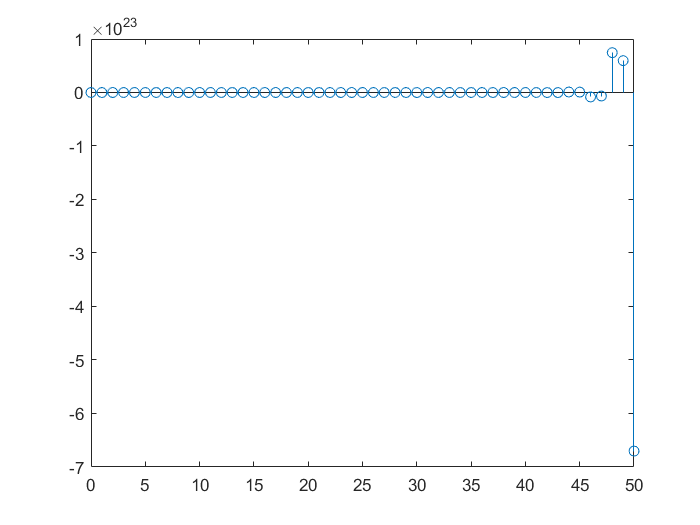

xn = 0.8.^n;
hn = (-0.9).^n;
yn = filter([1],[1,0,9],xn);
stem(n,yn);

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$

k = [-100:100];
w = (pi/100)*k;
hn = 0.9.^abs(n);
H = hn * (exp(-j*pi/100)).^(n'*k);
MagH = abs(H);
AngH = angle(H);
subplot(2,1,1); 
plot(w/pi,MagH);
grid;
xlabel('frequency in pi units'); ylabel('|H|1');
title('Magnitude Response');
subplot(2,1,2); 
plot(w/pi,AngH);
grid;
xlabel('frequency in pi units'); ylabel('Phase in pi Radians1');
title('Phase Response');


2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

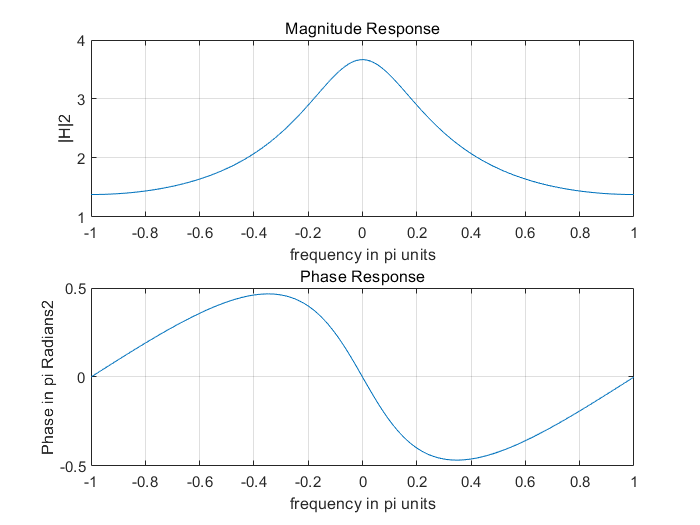

%직접 dtft를 하여 H를 구하고 식 나열
w = [-500:1:500]*pi/500;
H = 1./(1-0.5*exp(-j*w)) + 1./(1-0.4*exp(-j*w));
MagH = abs(H);
AngH = angle(H);
subplot(2,1,1); 
plot(w/pi,MagH);
grid;
xlabel('frequency in pi units'); ylabel('|H|2');
title('Magnitude Response');
subplot(2,1,2); 
plot(w/pi,AngH);
grid;
xlabel('frequency in pi units'); ylabel('Phase in pi Radians2');
title('Phase Response');

5. (P3.17) 

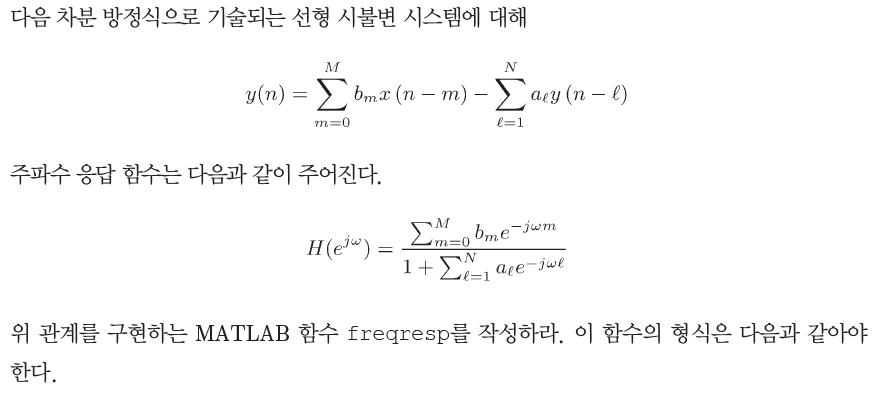

%function [H] = freqresp(b,a,w)
% H = frequency response array evaluated at w frequencies
% b = numerator coefficient array
% a = denominator coefficient array (a(1) = 1)
% w = frequency location array

%end

6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

% y(n)-0.95y(n-1)+0.9025y(n-2) = x(n)-x(n-2)


2) $y=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$